# Lesson 2: Combining Images and Matrices

## Pixel Art (Flag of Ireland)

In Lesson 2 we created the national flag of Ireland to the exact specifications set by the [Department of the Taoiseach](https://www.gov.ie/en/publication/adc448-the-national-flag/).  Recall how tedious it was to set the R-G-B colors for each individual pixel...

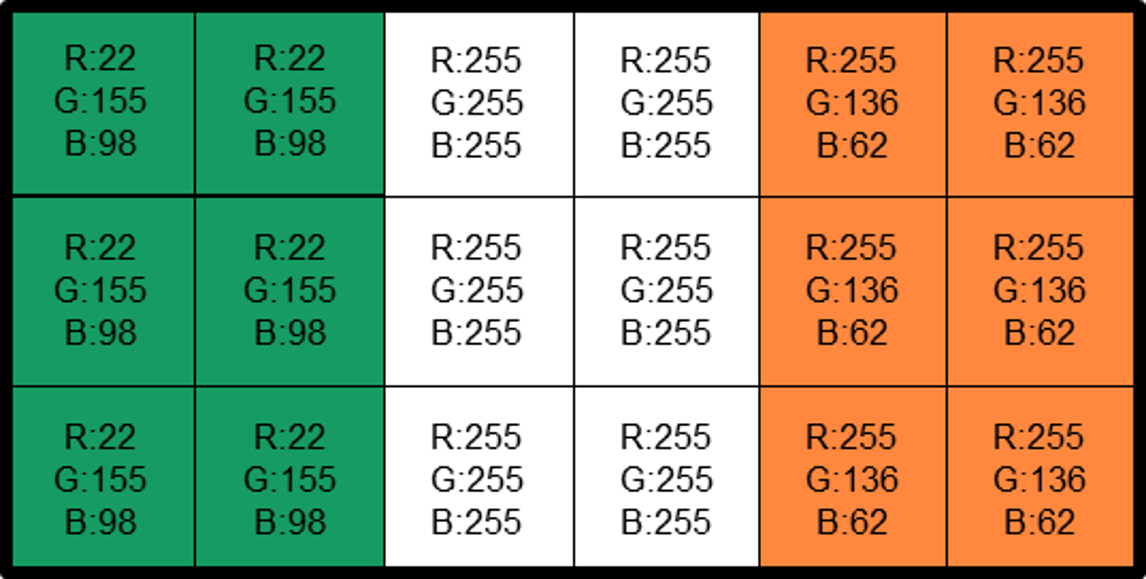

% Create a matrix named R containing all the red values in the image above
R = [ 22  22 255 255 255 255; ...
      22  22 255 255 255 255;  ...
      22  22 255 255 255 255];

% Create a matrix named G containing all the green values in the image above
G = [155 155 255 255 136 136; ...
     155 155 255 255 136 136; ...
     155 155 255 255 136 136];

% Create a matrix named B containing all the blue values in the image above
B = [ 98  98 255 255  62  62;  ...
      98  98 255 255  62  62;  ...
      98  98 255 255  62  62];

% Concatenate RGB pages and show combined image
Flag1 = uint8(cat(3,R,G,B)); % notice Flag1 is only 3 rows by 6 cols of pixels!
imshow(Flag1,"InitialMagnification",10000) % magnify to make visible

# Lessons 5 & 6: Applying Color Filters & Using Concatenation

## Color Filter Concatenation

Now that we've learned about concatenation, we could instead use the `newFilter` function from the [Pixels to Pictures](https://www.mathworks.com/academia/highschool/courseware/pixels-to-pictures.html) toolbox to create each color stripe, and then use concatenation to stitch the pieces together.

% Use the newFilter function to create green, white, and orange filters
green  = newFilter(300,200,[22 155 98]);
white  = newFilter(300,200,[255 255 255]);
orange = newFilter(300,200,[255 126,62]);

% Use square brackets to concatenate filters and show combined image
Flag2 = [green white orange];
imshow(Flag2)